n=200;
sigma = 1;
K=2;
rounding = 1e-4;
cluster_true = [repelem(1,n/2), repelem(-1,n/2)];
n_iter = 10; 
%%%%%%%%%%%%
sep = 3;
%%%%%%%%%%%%%
s = 10;
M = sqrt(sep^2 / 4 / s);

s=10;
rng(1);
n_iter = 10;

p_start = 10;
p_end = 1000;
n_grid = 20;
p_vec =  [round(linspace(p_start, p_end, n_grid))];
n_rep = 200;

n_pararell = 10;
n_p_chunk = n_grid/n_pararell;
p_vec_chunk = {};
clustering_acc_mat_chunk = {};

for i = 1:n_pararell
    p_vec_chunk{i} = p_vec( ((i-1)* n_p_chunk + 1) : (i*n_p_chunk) );
    clustering_acc_mat_chunk{i} = repmat( repelem(0, n_p_chunk ), n_rep, 1 );
end

parfor w = 1 : n_pararell
    for i = 1:length(p_vec_chunk{w})
        p = p_vec_chunk{w}(i)
        sparse_mean = [repelem(1,s), repelem(0,p-s)];
        mu_1 =  -M * sparse_mean;
        mu_2 =   M * sparse_mean;
       % norm(mu_1 - mu_2)
        mu_1_mat = repmat(mu_1, n/2,1);
        mu_2_mat = repmat(mu_2, n/2,1);
    
        for j = 1:n_rep
        %data generation
            x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
            A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                        %scaling
       
            % iterate
            clustering_acc_mat_chunk{w}(j, i) = interative_kmeans_SDP_Nov_30_2023_standardization(x, sigma, K, p, n_iter, rounding, n, cluster_true);
        end
    end
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 10 workers.
  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06
p = 948, acc before thres: 0.515000
1 th thresholding
n_G1=197, n_G2 =3
threshold = 3.702527
normalized difference:
ans =

  Columns 1 through 7

    0.9951    1.2562    0.4659    0.7443    1.6859    1.2838    0.3961

  Columns 8 through 14

    2.6132    2.1660    0.0890    1.2342    0.5368    0.7425    0.0356

  Columns 15 through 21

    1.2258    1.9791    0.4987    1.0453    1.3740    1.2277    0.0787

  Columns 22 through 28

    0.2814    0.9452    0.0681    0.0557    1.5851    0.5382    0.5565

  Columns 29 through 35

    0.5101    1.5274    0.5026    0.1410    0.9772    1.1457    1.4491

  Columns 36 through 42

    1.3386    0.1263    0.7900    0.1537    0.2554    1.7642    0.9570

  Columns 43 through 49

    0.0769    0.0216    0.3352    0.6296    0.9032    0.6908    0.9332

  Columns

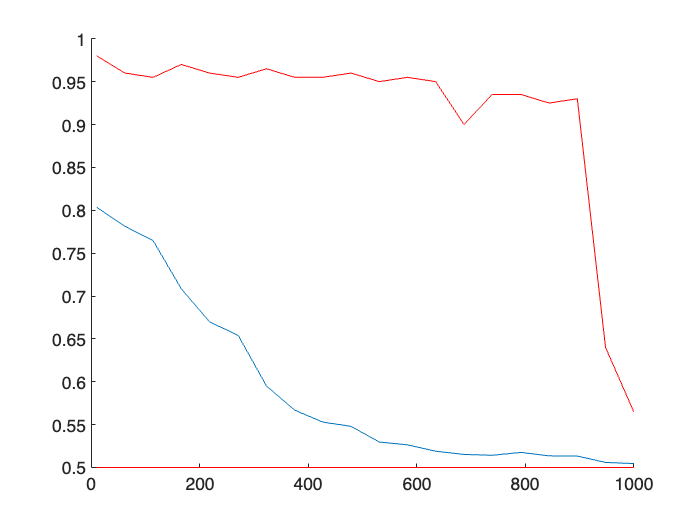

clustering_acc_mat = [];
for i = 1:n_pararell
    clustering_acc_mat = [clustering_acc_mat, clustering_acc_mat_chunk{i}];
    x = p_vec;                     
    y = mean(clustering_acc_mat,1);
    y_max = max(clustering_acc_mat);
    y_min = min(clustering_acc_mat);
end

figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off